# Sintonizacion PD lineal

close all; clc, clear
%% Datos
m = 1.6; % carbon 0.25
L = 0.268554; % carbon 0.008
kF = 0.7*9.81; % carbon 0.16
kM = 0.2;
km = log(1-0.9933)/-0.1; % carbon 1/0.03
Ix = 0.021915027; % carbon 2.496e-4
Iy = 0.022124548; % carbon 2.496e-4
Iz = 0.042349865; % carbon 3.996e-4

% Condiciones
PO = 0.18; %0.2
Ts = 0.5; %0.6
xi = sqrt((log(PO)^2)/((log(PO))^2+pi^2));
wd = -log(0.02)/(xi*Ts);
Pd = -wd*xi + wd*sqrt(xi^2-1);

## Momento en X

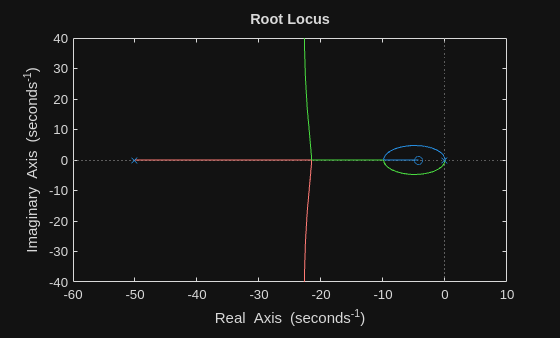

mot = tf(km,[1 km]);
dwtx = tf(1,[Ix 0 0]);

syst2 = series(mot, dwtx);

r = pole(syst2);
phi(1) = pi-atan(imag(Pd)/(real(Pd)-abs(r(1))));
phi(2) = pi-atan(imag(Pd)/(real(Pd)-abs(r(2))));
phi(3) = atan(imag(Pd)/(r(3) - real(Pd)));

phipd = -pi + sum(phi);
a = abs(real(Pd)) + imag(Pd)/tan(phipd);

pd = tf([1 a],1);
syst2pd = series(pd,syst2);
kDx = rlocfind(syst2pd,Pd);

kPx = a*kDx;
fprintf("Condicion de estabiidad %d\n", kPx < kDx*km && kPx > 0)

Condicion de estabiidad 1


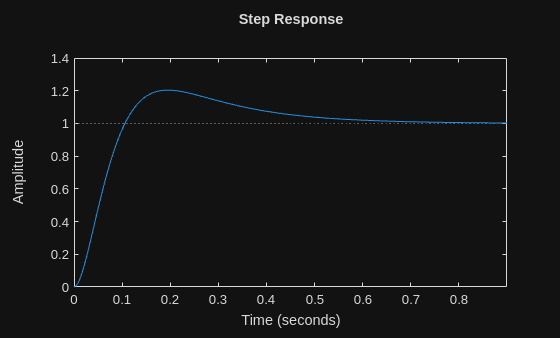

% simular
pd = tf([kDx, kPx],1);
sys_sim = series(pd,syst2);
sys_sim = feedback(sys_sim,1);
step(sys_sim)

## Momento en Y

dwty = tf(1,[Iy 0 0]);

syst3 = series(mot, dwty);

r = pole(syst3);
phi(1) = pi-atan(imag(Pd)/(real(Pd)-abs(r(1))));
phi(2) = pi-atan(imag(Pd)/(real(Pd)-abs(r(2))));
phi(3) = atan(imag(Pd)/(r(3) - real(Pd)));

phipd = -pi + sum(phi);
a = abs(real(Pd)) + imag(Pd)/tan(phipd);

pd = tf([1 a],1);
syst3pd = series(pd,syst3);
kDy = rlocfind(syst3pd,Pd);

kPy = a*kDy;
fprintf("Condicion de estabiidad %d\n", kPy < kDy*km && kPy > 0)

Condicion de estabiidad 1


% simular
pd = tf([kDy, kPy],1);
sys_sim = series(pd,syst3);
sys_sim = feedback(sys_sim,1);
step(sys_sim)

## Momento en Z

dwtz = tf(1,[Iz 0 0]);
syst4 = series(mot, dwtz);

r = pole(syst4);
phi(1) = pi-atan(imag(Pd)/(real(Pd)-abs(r(1))));
phi(2) = pi-atan(imag(Pd)/(real(Pd)-abs(r(2))));
phi(3) = atan(imag(Pd)/(r(3) - real(Pd)));

phipd = -pi + sum(phi);
a = abs(real(Pd)) + imag(Pd)/tan(phipd);

pd = tf([1 a],1);
syst4pd = series(pd,syst4);
kDz = rlocfind(syst4pd,Pd);

kPz = a*kDz;
fprintf("Condicion de estabiidad %d\n", kPz < kDz*km && kPz > 0)

Condicion de estabiidad 1


% simular
pd = tf([kDz, kPz],1);
sys_sim = series(pd,syst4);
sys_sim = feedback(sys_sim,1);
step(sys_sim)

fprintf("Ganancias:\n" + ...
    "    \tRoll ->  P: %f D: %f\n" + ...
    "    \tPitch -> P: %f D: %f\n" + ...
    "    \tYaw ->   P: %f D: %f\n", kPx, kDx, kPy, kDy, kPz, kDz);

Ganancias:
    	Roll ->  P: 1.498320 D: 0.352480
    	Pitch -> P: 1.512645 D: 0.355850
    	Yaw ->   P: 2.895440 D: 0.681153
